# Cointegration Exercise 

**Sinead Morrow : 23597852**

**Gaby Jacobs : **

**Abdul Cassiem : **

Objective: test for cointegration between the two interest rates (short term interest rates, e.g., CB policy rates or 3-month Government Treasury Bills) and determine how close to the predicted relationship the best model with cointegration yields. 

## Uncovered Interest Parity hypothesis

In international finance, the Fischer model predicts that the expected depreciation of a nominal exchange rate is a function of the interest rate differential. If the foreign interest rate increases relative to the domestic interest rate, we expect capital to flow out and the exchange rate to weaken (i.e. increase in our conventions: e = ZAR:USD).


$$E_t(e_{t+1})-e_t=i^{*}_t - i_t$$


Unfortunately, we don't have obvious measures of expected exchange rates (futures would have worked, but are hard to come by).

However, economic theory also suggest that expected depreciation$s_t=E_t(e_{t+1})-e_t$ should be stationary in equilibrium, unless there a non-stationary component to relative competitiveness of the two countries. 

At least we can do the following. If the two interest rates are each I(1), then we can test whether they are cointegrated as a minimum requirement for the theory. 

If the theory held exactly:


$$\left[\begin{array}{cc}
-1 & 1\end{array}\right]\left[\begin{array}{c}
i_{t}\\
i^{*}_{t}
\end{array}\right]=s_{t}\sim I(0)
\]$$


Again, in the real world, we expect deviations - there are many interest rates to choose from and the basic theory does not allow for a risk premium (which, if constant, would imply a constant in the cointegration relationship). 

## Import and visualize the data 

 clear
 load("cointegration_tutorial_data_2022.mat")
 

As always, we must be cognisant of the economic environtment we study with regards to the constancy of the data generating process. Before 1995, South Africa had a dual exchange rate system. After the GFC, the relationship and risk premia may have changed, so we restrict the sample for the first exercises.

Finally, numerical methods work best when data are similar in order of magnitude. Given that the level of a price index is meaningless, so we can rescale the two price series freely, so the simplest and clearest option is to let all variables start at the logarithmic value of the nominal exchange rate at the start of the sample

Create a logical vector with "True" in our sample and "False" elsewhere

sample = (dates>="01-Jan-1996"&dates<="01-Jun-2007");%(dates>="01-Jan-1995");

Rebase the price series to start at the same value as the exchange rate at the beginning of the sample, we will not rebase the interest rate series since it has fundamental meaning in levels:

E_ZAR_USD = E_ZAR_USD(sample,:); 
P_USA = P_USA(sample,:);
P_USA = (P_USA/P_USA(1))*E_ZAR_USD(1);
P_RSA = P_RSA(sample,:);
P_RSA = (P_RSA/P_RSA(1))*E_ZAR_USD(1);
dates = dates(sample,:);
e = log(E_ZAR_USD);
p_star = log(P_USA);
p = log(P_RSA);
i_RSA = I_3m_RSA(sample);
i_star = I_3m_USA(sample);
ppp_data = [e,p_star,p];
uip_data = [i_star,i_RSA];

Plotting the PPP data

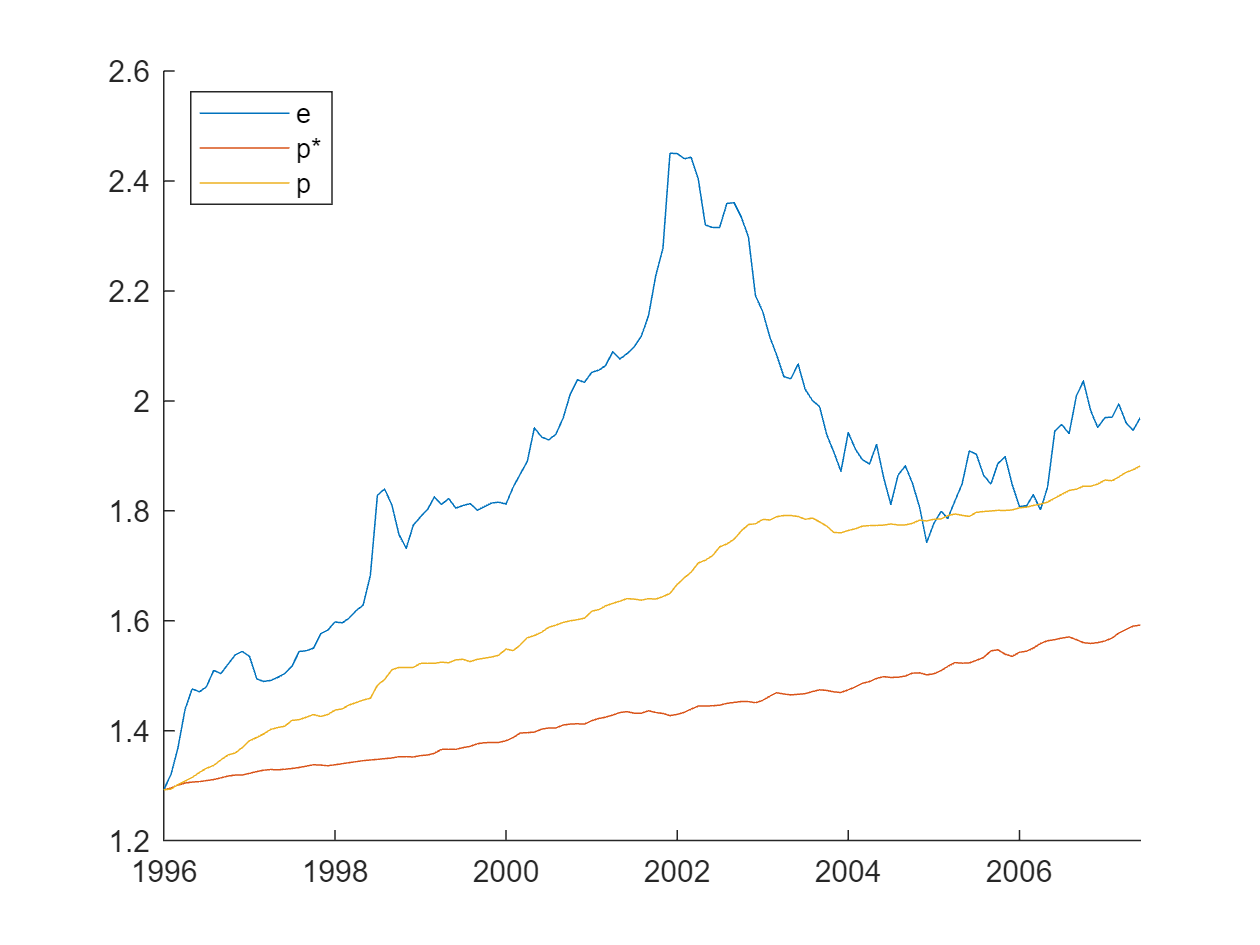

figure
hold on
plot(dates,ppp_data)
legend("e","p*","p",'Location',"best")

Plotting the UIP data

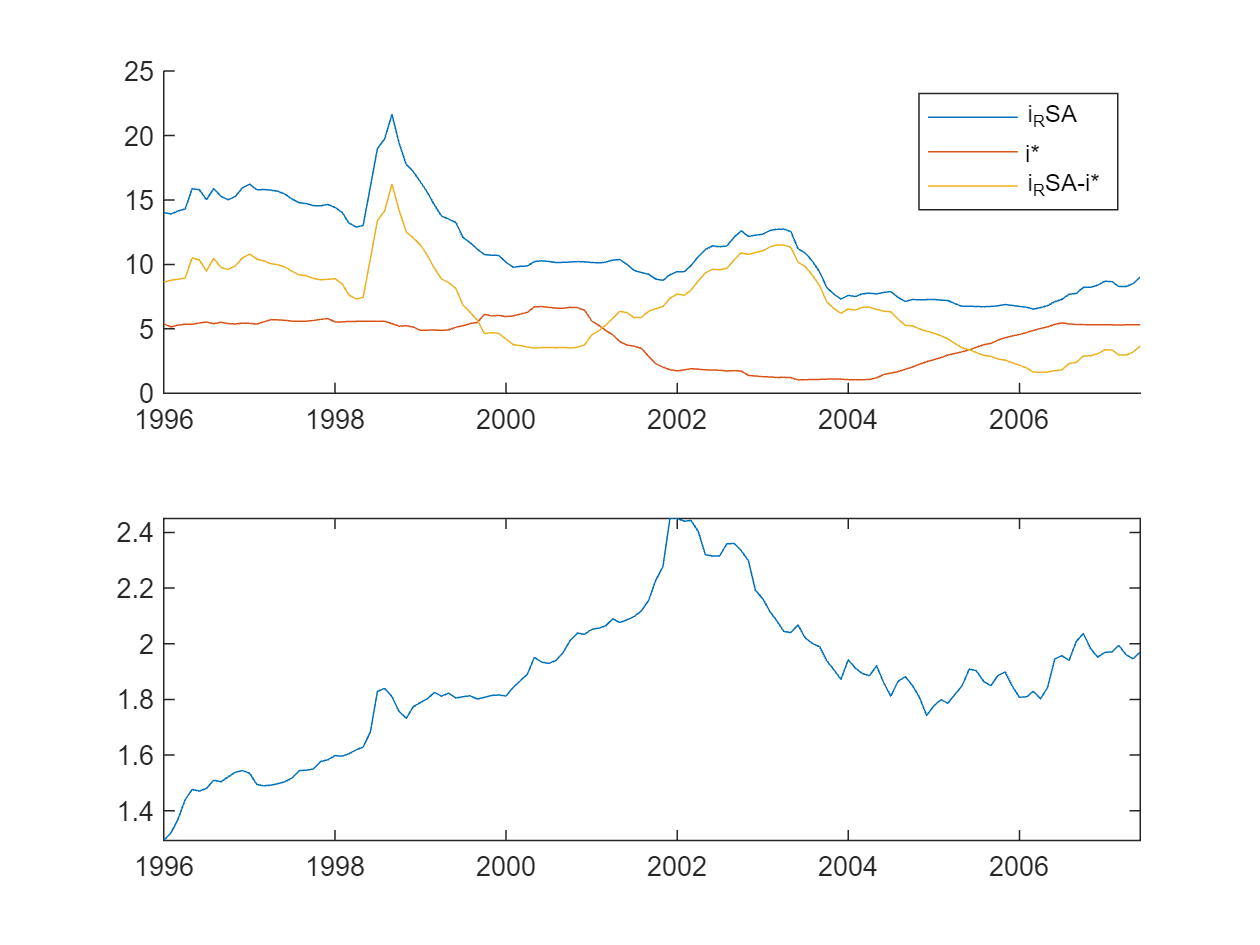

figure 
subplot(2,1,1)
hold on
plot(dates,i_RSA)
plot(dates,i_star)
plot(dates,i_RSA-i_star)
legend("i_RSA","i*","i_RSA-i*",'location',"best")
subplot(2,1,2)
plot(dates,e)

## 1. Formal unit root tests:

Augmented Dickey-Fuller test:

Since we have already done ADF tests for the PPP data in the tut, we have not replicated them again. 

It doesn't seem like there are any clear trends in the interest rate series, but the series might be deteriorating and would have a seasonality component so a cautious approach might want to allow for a trend. We conclude that the most logical test for the ADF test is that both series follow a unit root with drift against the alternatives that:

(i) interest rates are stationary around a deterministic trend

(ii) interest rates are stationary with drift

Using the test equation $\triangle y_t = a_0 + a_2 t +\gamma y_{t-1} +\sum_{i=2}^{p} \beta_i \triangle  y_{t-i+1}+ \varepsilon_t $,  we test the null $H_0: \gamma=a_2=0$, i.e. $y_t$ is a random walk with drift against the alternative $H_a: a_2 \neq 0, \gamma<0$, i.e.$y_t$ is a ARMA process around a deterministic trend)

We do the test for a range of lagged differences and use the BIC to choose the best model of the test.

**i**

against a trend stationary alternative: 


lags = [0:4]';
for lag = 1:5
    [reject(lag,1),pValue(lag,1),stat(lag,1),cValue(lag,1),reg] = adftest(i_RSA,'model','TS','lags',lag-1);
    BIC(lag,1) = reg.BIC;
end
i_adf_TS = table(lags,stat,cValue,pValue,reject,BIC)

i_adf_TS = 5×6 table
    lags     stat      cValue      pValue     reject     BIC  
    ____    _______    _______    ________    ______    ______

     0       -1.763    -3.4445     0.70544    false     266.29
     1      -3.0715    -3.4448     0.11797    false      233.9
     2      -3.1602    -3.4451    0.097273    false     237.25
     3      -3.1608    -3.4454    0.097181    false     241.25
     4      -2.2156    -3.4457     0.48463    false     233.47


against a stationary alternative with drift: 

for lag = 1:5
    [reject(lag,1),pValue(lag,1),stat(lag,1),cValue(lag,1),reg] = adftest(i_RSA,'model','ARD','lags',lag-1);
    BIC(lag,1) = reg.BIC;
end

i_adf_ARD = table(lags,stat,cValue,pValue,reject,BIC)

i_adf_ARD = 5×6 table
    lags     stat      cValue     pValue     reject     BIC  
    ____    _______    _______    _______    ______    ______

     0      -1.1329    -2.8834    0.67747    false     263.25
     1      -1.7666    -2.8836    0.39933    false     235.23
     2      -1.8303    -2.8838    0.37136    false     238.97
     3      -1.8006    -2.8839    0.38436    false     243.14
     4      -1.7377    -2.8841    0.41194    false     231.09


**i***

against a trend stationary alternative: 

for lag = 1:5
    [reject(lag,1),pValue(lag,1),stat(lag,1),cValue(lag,1),reg] = adftest(i_star,'model','TS','lags',lag-1);
    BIC(lag,1) = reg.BIC;
end
i_star_adf_TS = table(lags,stat,cValue,pValue,reject,BIC)

i_star_adf_TS = 5×6 table
    lags      stat      cValue     pValue     reject      BIC  
    ____    ________    _______    _______    ______    _______

     0       0.35871    -3.4445     0.9985    false     -69.725
     1      -0.75117    -3.4448    0.96646    false     -120.94
     2       -1.0908    -3.4451    0.92586    false      -123.3
     3       -1.3533    -3.4454    0.86939    false     -119.08
     4       -1.7648    -3.4457    0.70435    false        -117


against a stationary alternative with drift: 

for lag = 1:5
    [reject(lag,1),pValue(lag,1),stat(lag,1),cValue(lag,1),reg] = adftest(i_star,'model','ARD','lags',lag-1);
    BIC(lag,1) = reg.BIC;
end

i_star_adf_ARD = table(lags,stat,cValue,pValue,reject,BIC)

i_star_adf_ARD = 5×6 table
    lags      stat      cValue     pValue     reject      BIC  
    ____    ________    _______    _______    ______    _______

     0      -0.59169    -2.8834    0.86724    false     -70.822
     1       -1.0441    -2.8836    0.71642    false     -125.74
     2       -1.3859    -2.8838    0.56636    false     -128.17
     3       -1.5888    -2.8839    0.47729    false     -124.02
     4       -1.8682    -2.8841     0.3547    false     -121.84


The ADF test results suggest that both interest rate series, i and i*, follow a unit root process. Therefore conclude that interest rates follow at least an I(1) process.

## 2. Estimate Unrestricted VAR and assess adequacy

Create an model structure for a VAR(2) with two variables. 

**I have included 2 lags which may seem odd but will send a voicenote to explain why I did that now (idk how to type it at the moment).**

First, we consider the estimation without a trend as an example of how to detect problems.

num_variables = 2;
num_lags = 2;
uip_var_no_trend = varm(num_variables,num_lags);
uip_var_no_trend.Trend = 0; % This option means we are excluding a trend

% estimate the model using the data:
uip_var_no_trend_est = estimate(uip_var_no_trend,uip_data);

% summarize the results:
summarize(uip_var_no_trend_est)

 
   AR-Stationary 2-Dimensional VAR(2) Model
 
    Effective Sample Size: 136
    Number of Estimated Parameters: 10
    LogLikelihood: -38.4223
    AIC: 96.8445
    BIC: 125.971
 
                     Value      StandardError    TStatistic      PValue   
                   _________    _____________    __________    ___________

    Constant(1)     0.051596      0.044568          1.1577         0.24699
    Constant(2)      0.17631       0.16789          1.0501         0.29365
    AR{1}(1,1)        1.5787      0.069286          22.786     6.3382e-115
    AR{1}(2,1)       0.15205       0.26101         0.58253         0.56021
    AR{1}(1,2)     -0.021238      0.020265          -1.048         0.29464
    AR{1}(2,2)        1.4255      0.0

uip_var_no_trend_resid = infer(uip_var_no_trend_est,uip_data);

## 2.1 Assess congruency

%resid_plotter(dates,uip_var_no_trend_resid,num_lags)

Formal Ljung-Box tests:

Lags = [3,6,9,12]';

for i = 1:2
    [reject,pValue,stat,cValue] = lbqtest(uip_var_no_trend_resid(:,i),'Lags',Lags);
    var_uip_no_trend_res_lbqtest = table(Lags,stat,cValue,pValue,reject)
end

var_uip_no_trend_res_lbqtest = 4×5 table
    Lags     stat     cValue     pValue     reject
    ____    ______    ______    ________    ______

      3     2.3292    7.8147     0.50695    false 
      6     8.2863    12.592     0.21787    false 
      9     16.343    16.919    0.060063    false 
     12     17.494    21.026     0.13195    false 


var_uip_no_trend_res_lbqtest = 4×5 table
    Lags     stat     cValue    pValue     reject
    ____    ______    ______    _______    ______

      3     1.8206    7.8147    0.61047    false 
      6     8.7319    12.592    0.18923    false 
      9     8.9379    16.919    0.44303    false 
     12     9.9224    21.026    0.62277    false 


## 2.2 Assess stability

A simple eye-ball test (not valid statistically) is to see how long it takes the IRFs to return to zero. If it takes very long, we suspect one or more unit roots. (Note: here we don't care about identification, just stability

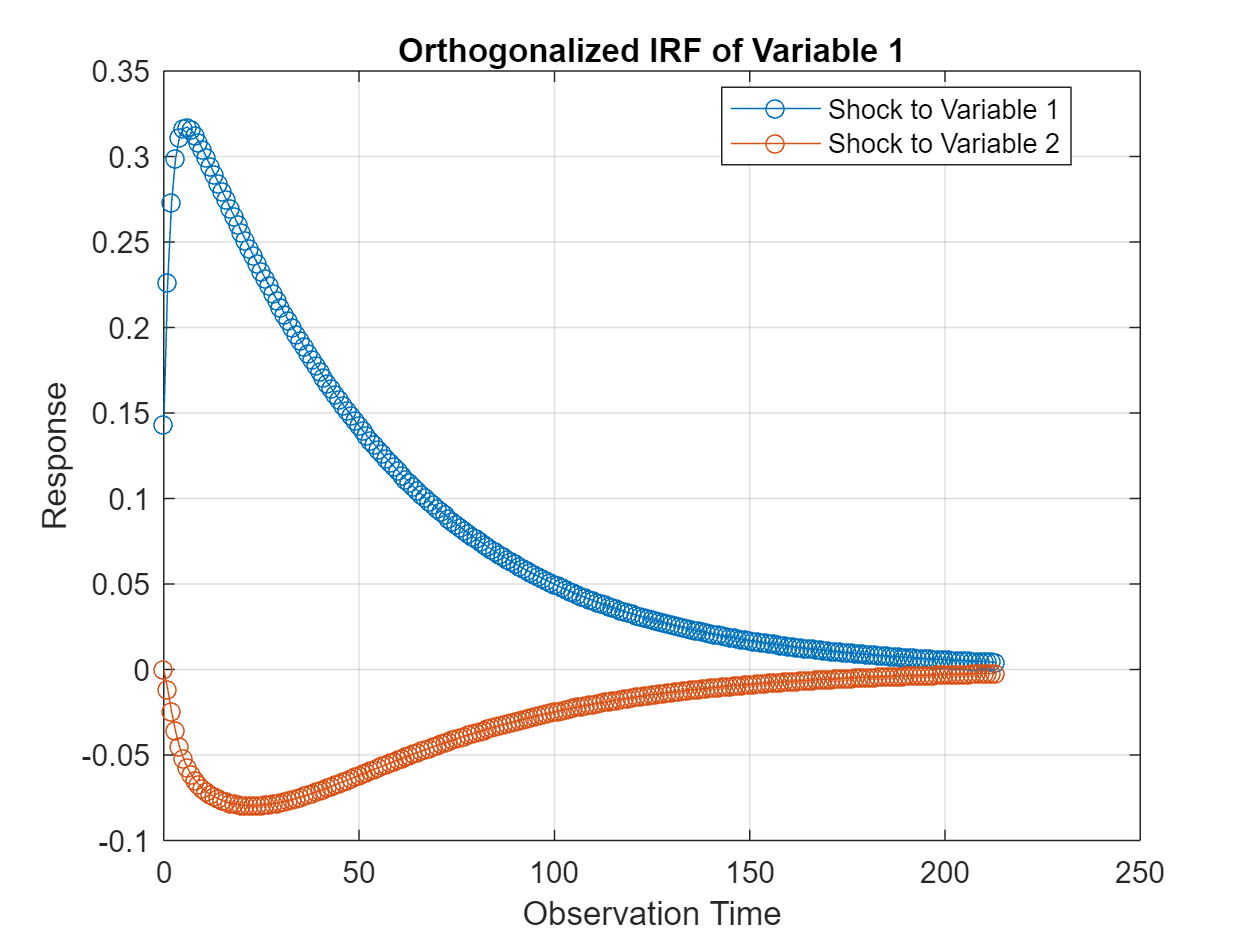

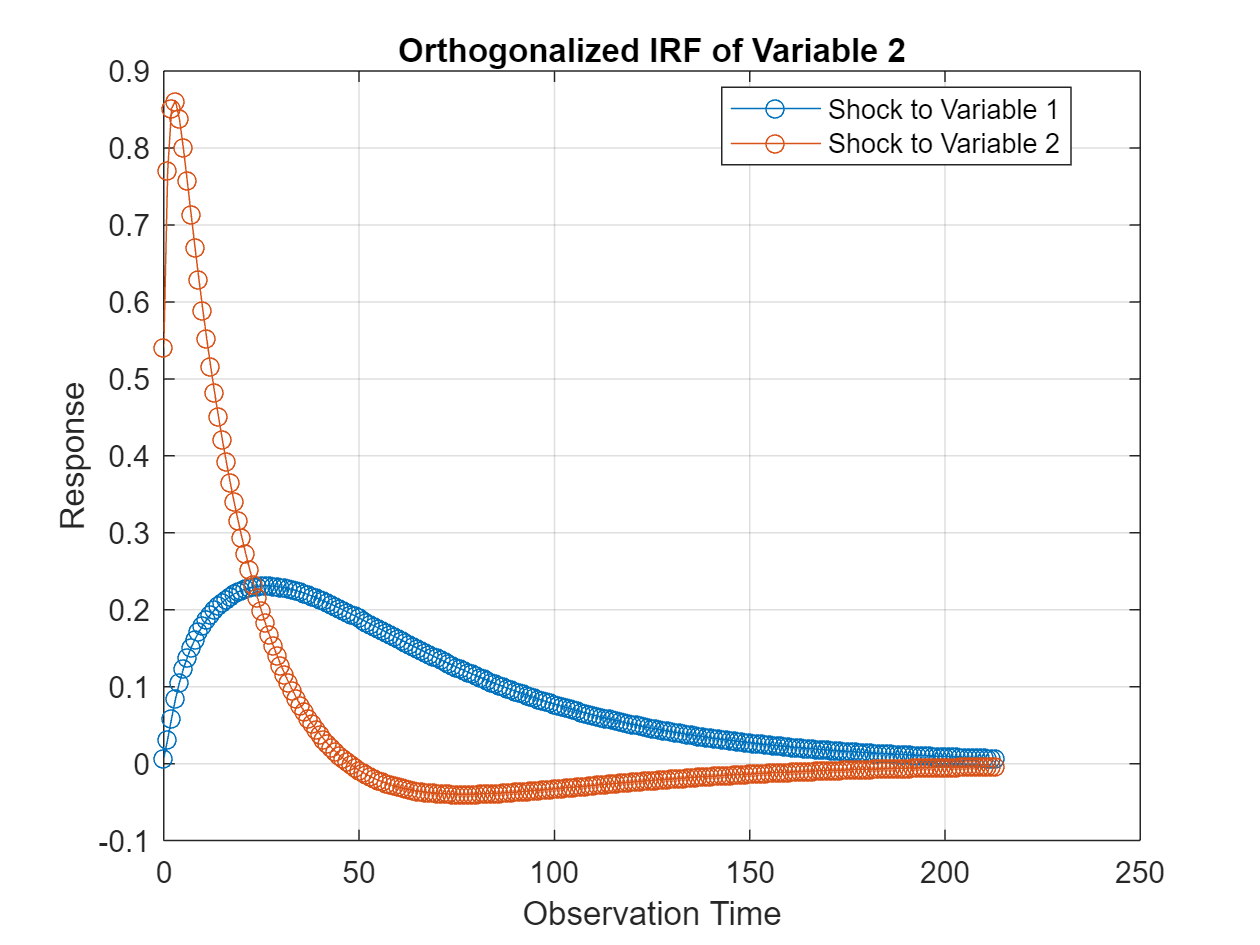

armairf(uip_var_no_trend_est.AR,[],"InnovCov",uip_var_no_trend_est.Covariance)

## Using the stability rule we derived for a VAR

companion_matrix = VAR_companion(uip_var_no_trend_est.AR);
abs_characteristic_roots = abs(eig(companion_matrix))

abs_characteristic_roots =     0.4996
    0.5759
    0.9786
    0.9502


max(abs_characteristic_roots)

ans = 0.9786

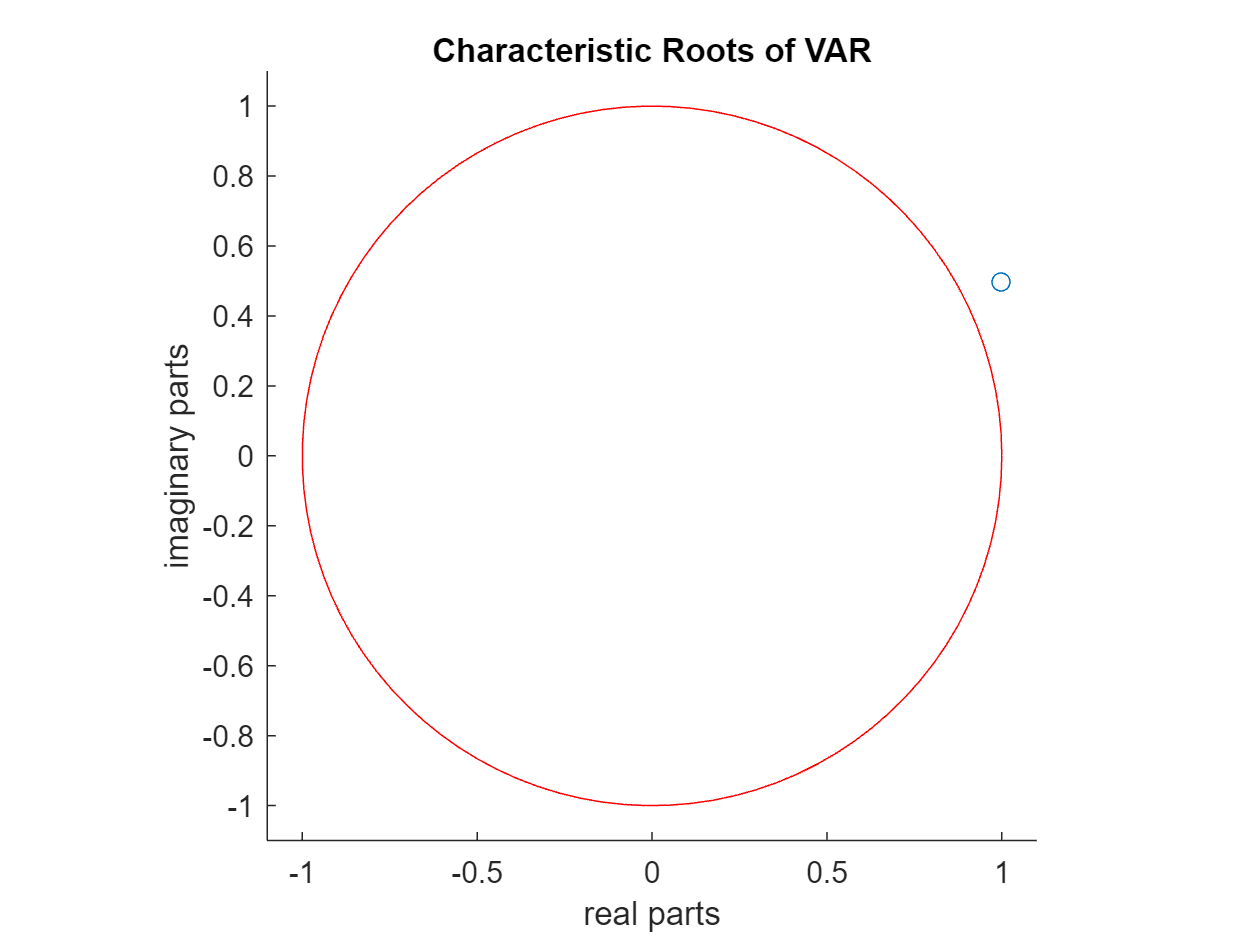

phi = linspace(0,2*pi,100)';
[x,y] = pol2cart(phi,ones(100,1));
        
figure
hold on
plot(eig(companion_matrix),'o')
plot(x,y,'r')
title('Characteristic Roots of VAR')
xlabel('real parts')
ylabel('imaginary parts')
axis([-1.1 1.1 -1.1 1.1])
axis square

While the system is not explosive when looking at the IRFs the systems take over 100 horizons to return to zero which is relatively long, and the fact that the characteristc root is lying outside the unit root circle is indicative of one of two things; either the VAR without a trend is insufficiengt or there is cointegration. Thus we move to adding a trend :).

Adding a trend:

uip_var_trend1 = varm(num_variables,num_lags);
uip_var_trend1.Trend = [NaN, NaN]'; % this is allows a trend in each eqn

% estimate the model using the data:
uip_var_trend1_est = estimate(uip_var_trend1,uip_data);

% summarize the results:
summarize(uip_var_trend1_est)

 
   AR-Stationary 2-Dimensional VAR(2) Model with Linear Time Trend
 
    Effective Sample Size: 136
    Number of Estimated Parameters: 12
    LogLikelihood: -35.7747
    AIC: 95.5493
    BIC: 130.501
 
                      Value       StandardError    TStatistic      PValue   
                   ___________    _____________    __________    ___________

    Constant(1)       0.085014        0.12129        0.70094         0.48334
    Constant(2)         1.1384        0.44836          2.539        0.011116
    AR{1}(1,1)          1.5793       0.069291         22.793     5.4302e-115
    AR{1}(2,1)         0.16848        0.25615        0.65776         0.51069
    AR{1}(1,2)       -0.021879       0.020374        -1.0739         0.28288
    AR{1}

The trend is signficant in the 3 month RSA interest rate series but not in the 3 month USA series so we drop it from that regression: 

num_lags = 2; % trust me on this for now
uip_var_trend2 = varm(num_variables,num_lags);
uip_var_trend2.Trend = [0, NaN]'; % this is allows a trend in eqn 2 & 3

% estimate the model using the data:
uip_var_trend2_est = estimate(uip_var_trend2,uip_data);

% summarize the results:
summarize(uip_var_trend2_est)

 
   AR-Stationary 2-Dimensional VAR(2) Model with Linear Time Trend
 
    Effective Sample Size: 136
    Number of Estimated Parameters: 11
    LogLikelihood: -35.8185
    AIC: 93.6371
    BIC: 125.676
 
                     Value       StandardError    TStatistic      PValue   
                   __________    _____________    __________    ___________

    Constant(1)      0.051596       0.044568         1.1577         0.24699
    Constant(2)        1.1374        0.44835         2.5369        0.011185
    AR{1}(1,1)         1.5787       0.069286         22.786     6.3382e-115
    AR{1}(2,1)        0.16847        0.25615        0.65769         0.51074
    AR{1}(1,2)      -0.021238       0.020265         -1.048         0.29464
    AR{1}(2,2) <

## 2.1 Assess residual structure

## store and plot the residuals

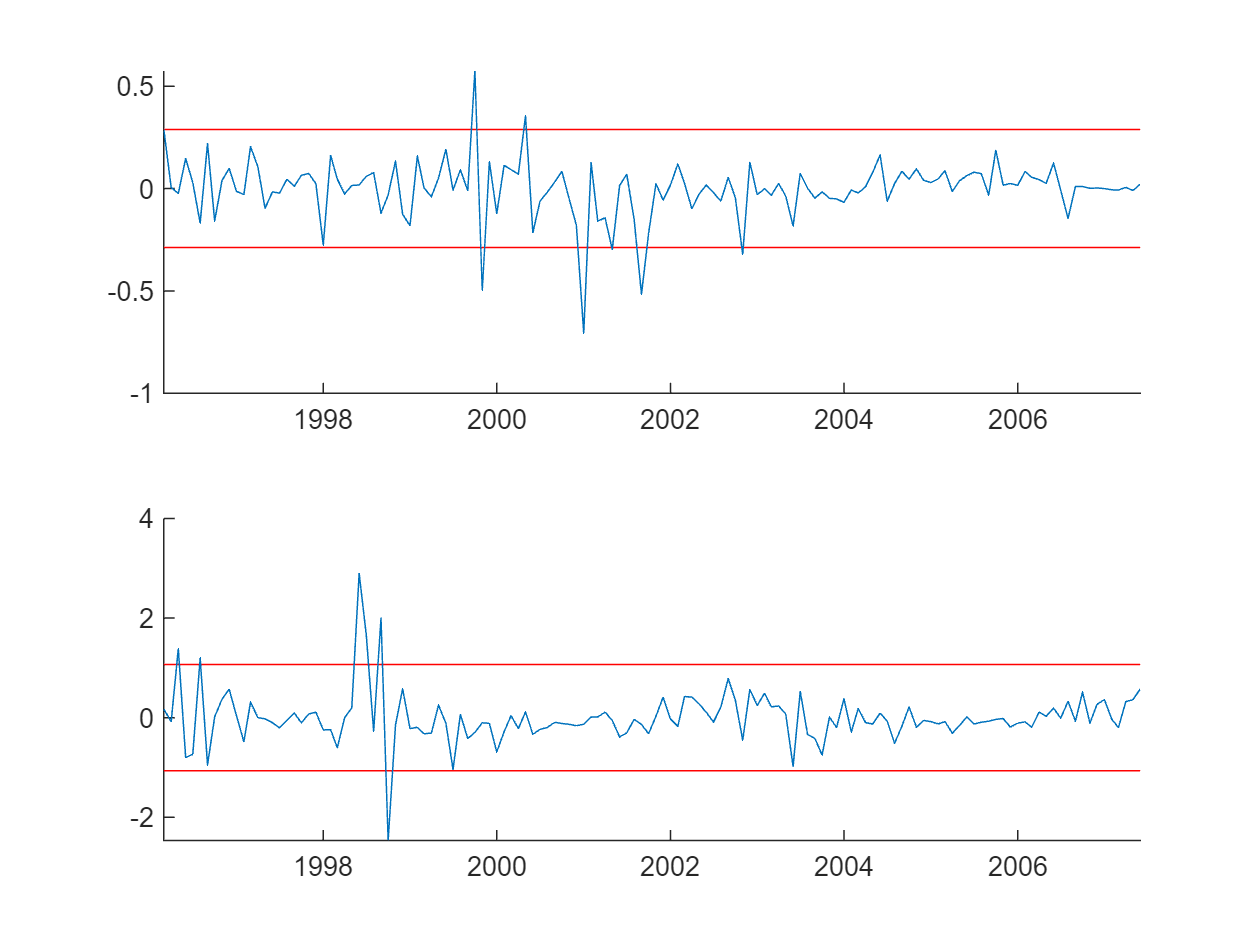

uip_var_trend2_resid = infer(uip_var_trend2_est,uip_data);
lower_bounds = mean(uip_var_trend2_resid)-2*std(uip_var_trend2_resid);
upper_bounds = mean(uip_var_trend2_resid)+2*std(uip_var_trend2_resid);

figure
for i = 1:2
    subplot(2,1,i)
    hold on
    line([dates(num_lags+1),dates(end)],[lower_bounds(i) lower_bounds(i)],'Color','r')
    line([dates(num_lags+1),dates(end)],[upper_bounds(i) upper_bounds(i)],'Color','r')
    plot(dates(num_lags+1:end),uip_var_trend2_resid(:,i)) 
end

## Formal Ljung-Box q tests

null hypothesis: no auto correlation up to lag h

Lags = [3,6,9,12]';

for i = 1:2
    [reject,pValue,stat,cValue] = lbqtest(uip_var_trend2_resid(:,i),'Lags',Lags);
    var_uip_res_lbqtest = table(Lags,stat,cValue,pValue,reject)
end

var_uip_res_lbqtest = 4×5 table
    Lags     stat     cValue     pValue     reject
    ____    ______    ______    ________    ______

      3     2.3292    7.8147     0.50695    false 
      6     8.2863    12.592     0.21787    false 
      9     16.343    16.919    0.060063    false 
     12     17.494    21.026     0.13195    false 


var_uip_res_lbqtest = 4×5 table
    Lags     stat     cValue    pValue     reject
    ____    ______    ______    _______    ______

      3     3.4879    7.8147    0.32233    false 
      6      8.848    12.592    0.18231    false 
      9     9.1763    16.919    0.42117    false 
     12      10.24    21.026    0.59489    false 


## 2.2 Assess stability

Informally:

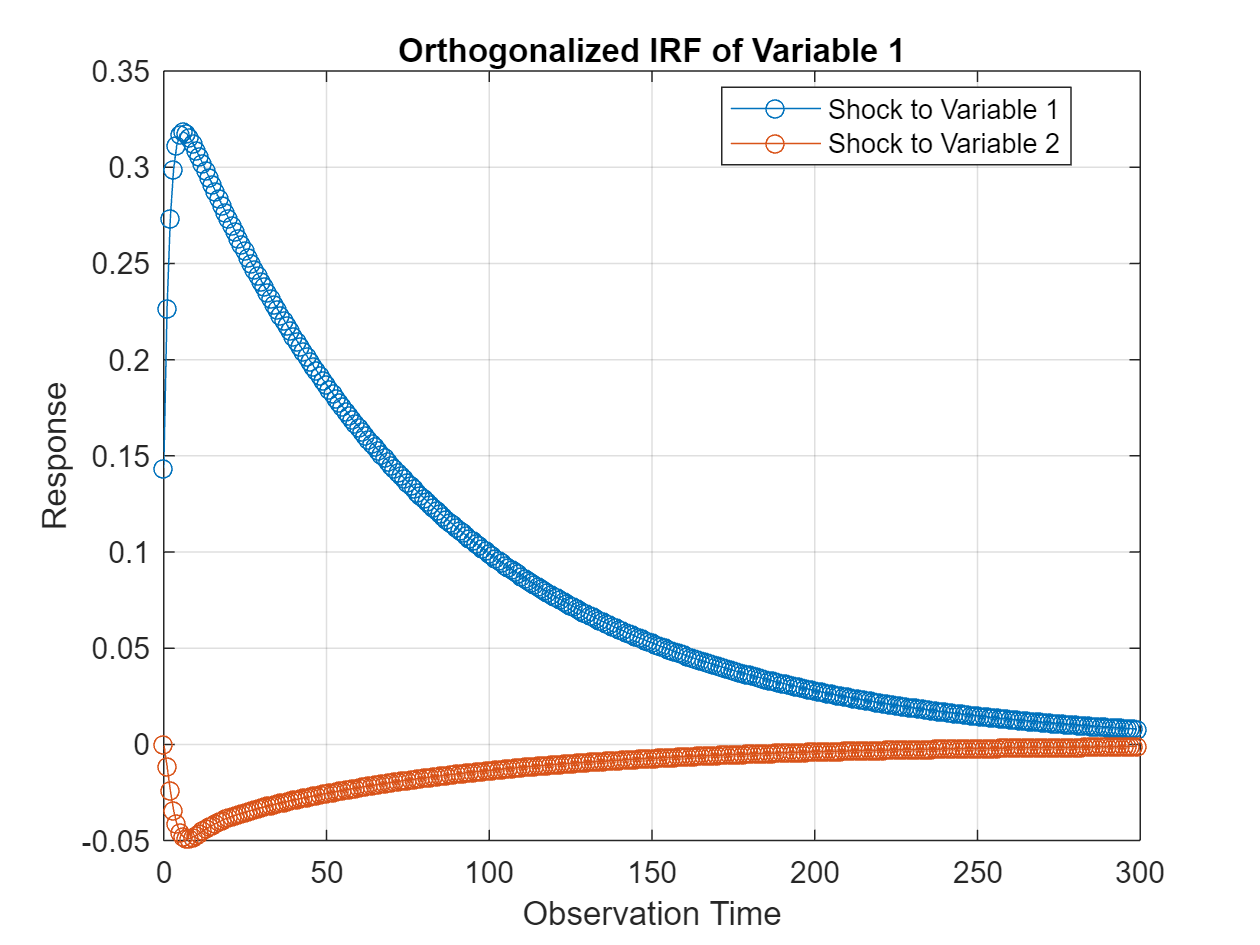

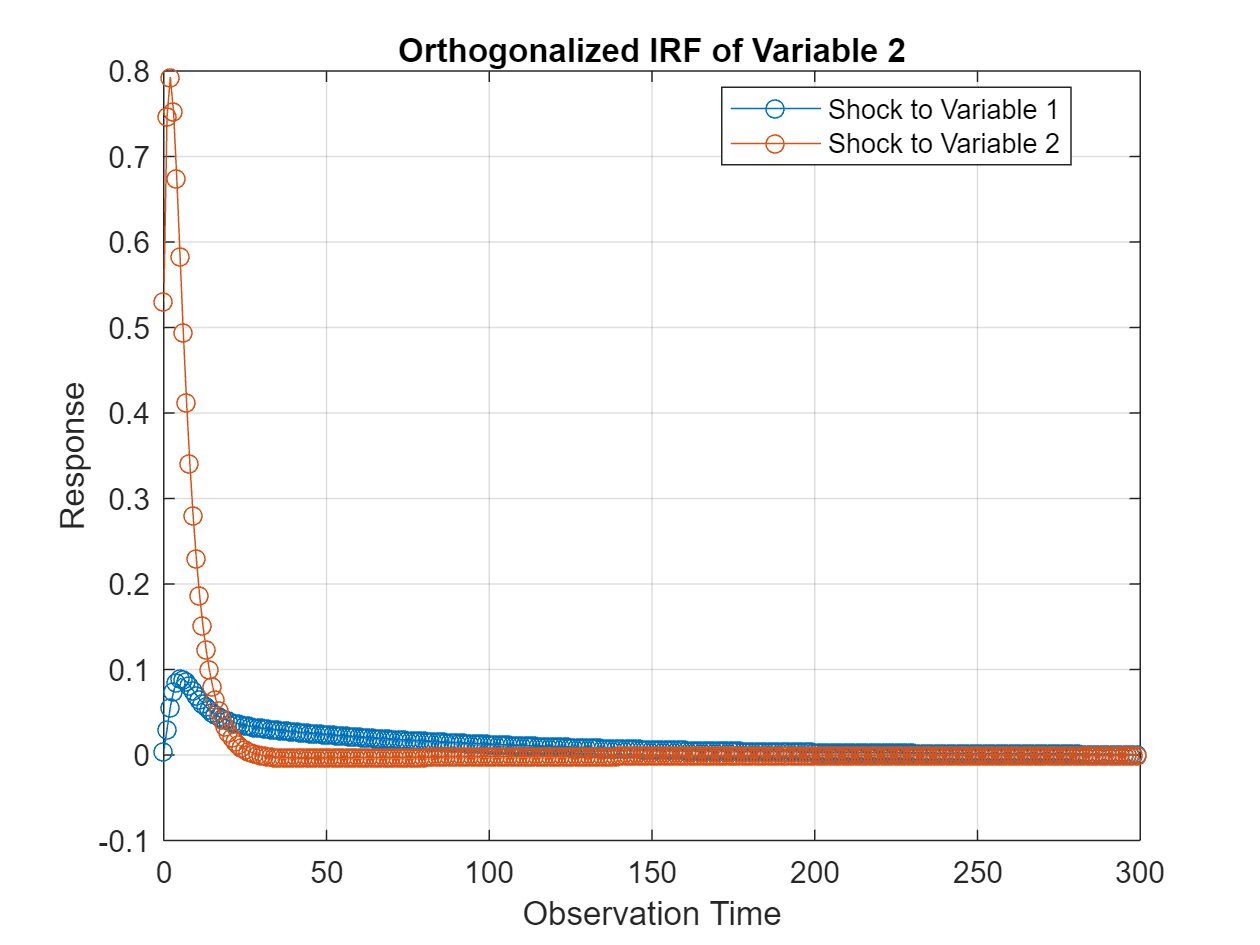

armairf(uip_var_trend2_est.AR,[],"InnovCov",uip_var_trend2_est.Covariance,'NumObs',300)

companion_matrix = VAR_companion(uip_var_no_trend_est.AR);
abs_characteristic_roots = abs(eig(companion_matrix))

abs_characteristic_roots =     0.4996
    0.5759
    0.9786
    0.9502


max(abs_characteristic_roots)

ans = 0.9786

phi = linspace(0,2*pi,100)';
[x,y] = pol2cart(phi,ones(100,1));
        
figure
hold on
plot(eig(companion_matrix),'o')
plot(x,y,'r')
title('Characteristic Roots of VAR')
xlabel('real parts')
ylabel('imaginary parts')
axis([-1.1 1.1 -1.1 1.1])
axis square

## 3. Determine the cointegration rank via the Johansen test

Note: we reduce the number of lags by 1 when conducting cointegration tests and setting up the VECM.

num_lags = 1

num_lags = 1

[reject,pValue,stat,cValue,mles] = jcitest(uip_data,'model','H1','lags',num_lags,'test','maxeig');


************************
Results Summary (Test 1)

Data: uip_data
Effective sample size: 136
Model: H1
Lags: 1
Statistic: maxeig
Significance level: 0.05


r  h  stat      cValue   pValue   eigVal   
----------------------------------------
0  0  4.2239    14.2644  0.8348   0.0306  
1  0  1.1865    3.8415   0.3733   0.0087  


[reject,pValue,stat,cValue,mles] = jcitest(uip_data,'model','H1','lags',num_lags,'test','trace');


************************
Results Summary (Test 1)

Data: uip_data
Effective sample size: 136
Model: H1
Lags: 1
Statistic: trace
Significance level: 0.05


r  h  stat      cValue   pValue   eigVal   
----------------------------------------
0  0  5.4104    15.4948  0.7678   0.0306  
1  0  1.1865    3.8415   0.3733   0.0087  


[reject,pValue,stat,cValue] = egcitest(uip_data)

reject = logical
   0


pValue = 0.9636

stat = -0.4875

cValue = -3.3822

We fail to reject the null hypothesis of a cointegration rank less than or equal to 0 and fail to reject a cointegration rank of less than or equal to 1. There is weak evidence of at most one cointegrating vector. 

The Engle-Granger cointegration test fails to reject the null hypothesis of no cointegration. It is unlikely that the interest rate series is cointegrated. 

Testing for stationarity within the system. 

[reject,pValue] = jcontest(uip_data,1,'BVec',{[1 0]',[0 1]'})

reject = 1×2 logical array
   1   0


pValue =     0.0136    0.4088


var_names = ["i_RSA", "i*"]';
reject = reject';
pValue = pValue';

stationarity_tests = table(var_names,reject,pValue)

stationarity_tests = 2×3 table
    var_names    reject     pValue 
    _________    ______    ________

     "i_RSA"     true      0.013583
     "i*"        false      0.40884


## 4. Estimate restricted VECM for interpretation

num_var = 2;
num_coint = 1;
num_lag = 1;
uip_vecm = vecm(num_var,num_coint,num_lag);
uip_vecm.CointegrationTrend = NaN;

uip_vecm_est = estimate(uip_vecm,uip_data,'Model','H1');
summarize(uip_vecm_est)

 
   2-Dimensional Rank = 1 VEC(1) Model
 
    Johansen Model: H1
    Effective Sample Size: 136
    Number of Estimated Parameters: 10
    LogLikelihood: -39.0155
    AIC: 98.031
    BIC: 127.158
 
                          Value       StandardError    TStatistic      PValue  
                        __________    _____________    __________    __________

    Constant(1)           0.020988       0.033512        0.62629        0.53113
    Constant(2)            0.21293         0.1258         1.6926       0.090529
    Adjustment(1,1)      -0.008003       0.012361       -0.64743        0.51736
    Adjustment(2,1)      -0.091601       0.046402        -1.9741       0.048374
    Impact(1,1)          0.0019974      0.0030851        0.64743        0.51736
  

results = summarize(uip_vecm_est)

results = struct with fields:
               Description: "2-Dimensional Rank = 1 VEC(1) Model"
                     Model: "H1"
                SampleSize: 136
    NumEstimatedParameters: 10
             LogLikelihood: -39.0155
                       AIC: 98.0310
                       BIC: 127.1576
                     Table: [12×4 table]
                Covariance: [2×2 double]
               Correlation: [2×2 double]


isA = contains(results.Table.Properties.RowNames,'Adjustment');
Aresults = results.Table(isA,:)

Aresults = 2×4 table
                         Value      StandardError    TStatistic     PValue 
                       _________    _____________    __________    ________

    Adjustment(1,1)    -0.008003      0.012361        -0.64743      0.51736
    Adjustment(2,1)    -0.091601      0.046402         -1.9741     0.048374


## ormalized cointegration relationship

uip_vecm_est.Cointegration

ans =    -0.2496
    0.3204


uip_coint_B_normalized = uip_vecm_est.Cointegration/uip_vecm_est.Cointegration(1)

uip_coint_B_normalized =     1.0000
   -1.2836


uip_coint_const_normalized = uip_vecm_est.CointegrationConstant/uip_vecm_est.Cointegration(1)

uip_coint_const_normalized = 9.3229

uip_coint_rel = (uip_vecm_est.CointegrationConstant + uip_data*[uip_vecm_est.Cointegration]);

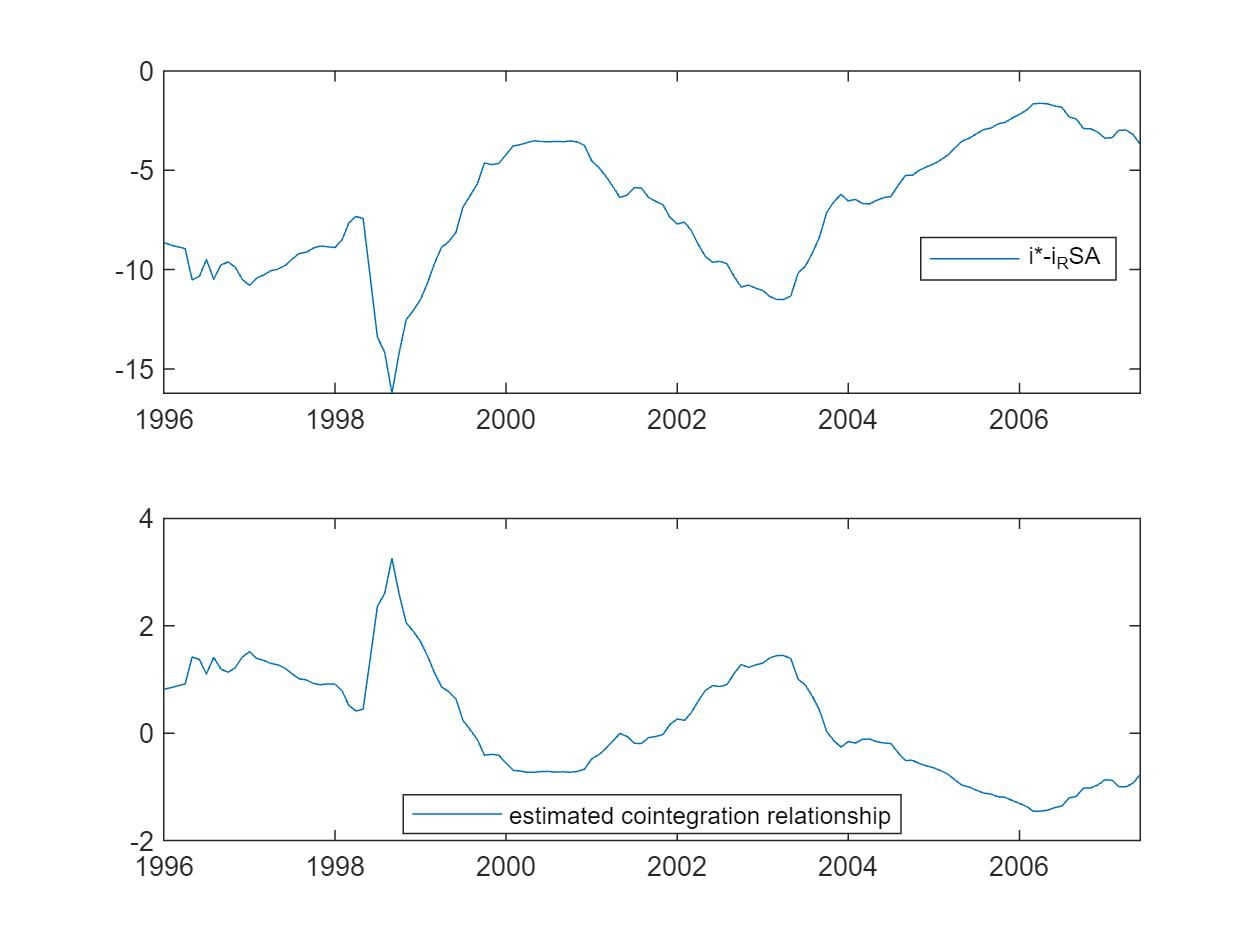

figure
subplot(2,1,1)
plot(dates,i_star-i_RSA)
legend('i*-i_RSA','location','best')
subplot(2,1,2)
plot(dates,uip_coint_rel)
legend('estimated cointegration relationship','location','best')

uip_vecm_resid = infer(uip_vecm_est, uip_data);
T_resid = length(uip_vecm_resid(:,1));
% normality tests:
for i=1:2
    [~,p_value(i)]=jbtest(uip_vecm_resid(:,i));
end

p_value

p_value = 1.0e-03 *

    1.0000    1.0000


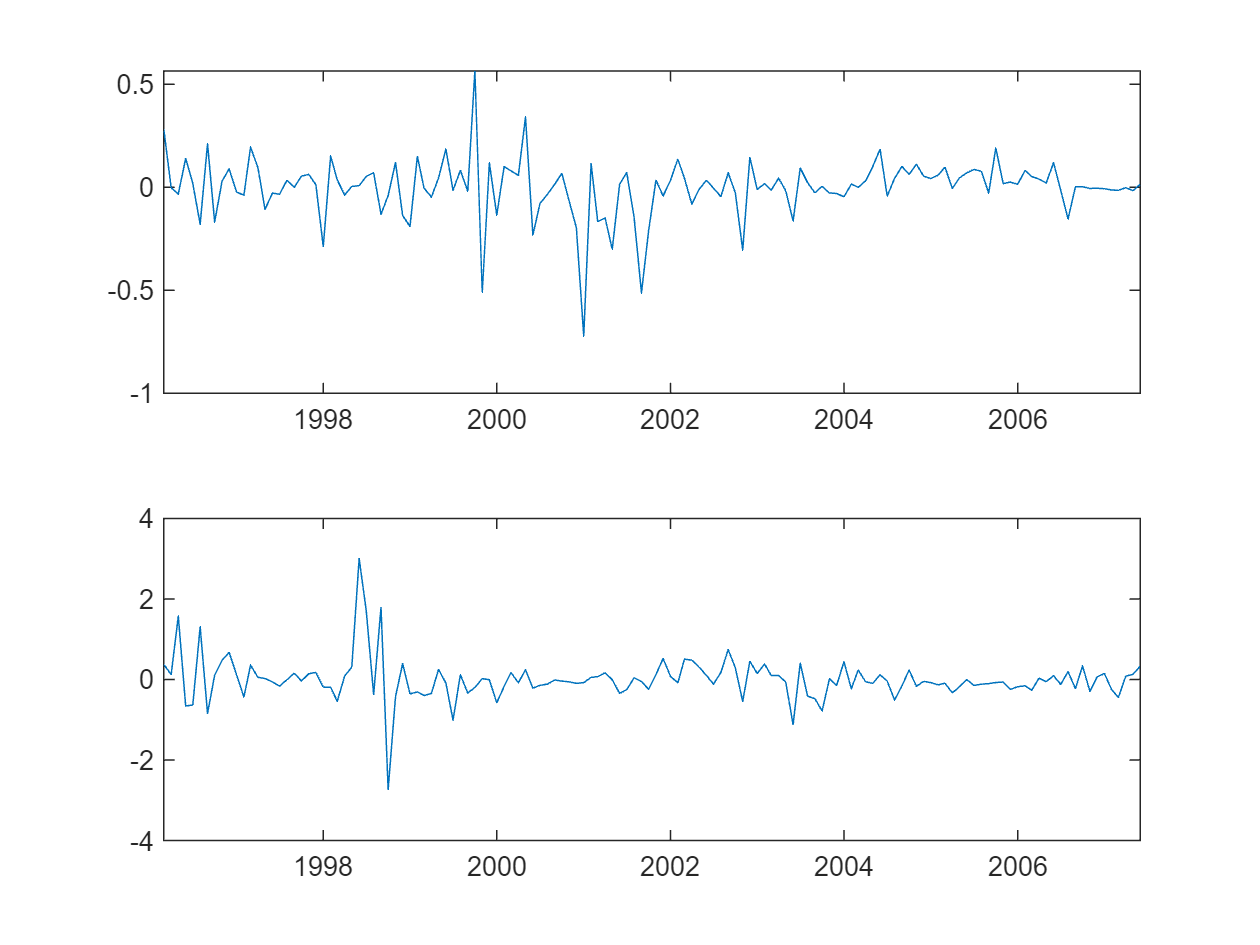


figure
for i = 1:2
    subplot(2,1,i)
    plot(dates(end-T_resid+1:end),uip_vecm_resid(:,i))
end

## Test weak exogeneity of each series:

[reject,pValue,stat,cValue] = jcontest(uip_data,num_coint,'ACon',{[1 0]',[0 1]'},'lags',num_lag,'model','H1');
var_names = ["i_star","i_RSA"]';
reject = reject';
pValue = pValue';
stat = stat';
cValue = cValue';
uip_vecm_weak_exogeneity = table(var_names,stat,cValue,pValue,reject)

uip_vecm_weak_exogeneity = 2×5 table
    var_names     stat      cValue     pValue     reject
    _________    _______    ______    ________    ______

    "i_star"     0.30213    3.8415     0.58255    false 
    "i_RSA"        2.764    3.8415    0.096409    false 


Both variables are weakly exogenous to the system, further indicates that there is most likely no cointegration between the series.

## Test UIP:

[reject,pValue] = jcontest(uip_data,1,'BVec',{[1 -1]'})

reject = logical
   0


pValue = 0.5936

## Jointly testing the PPP and UIP hypotheses

I don't know whether or not to do a joint test? Up to you, Hylton and/or Gideon did it last year..will ask gideon if we need to but here be the code will interpret later.

We can state both hypotheses simulateously as: 


$$\left[\begin{array}{ccccc}
1 & 1 & -1 & 0 & 0\\
0&0&0&-1& 1
 \end{array}\right]\left[\begin{array}{c}
e_{t}\\
p^*_t\\
p_t\\
i_{t}\\
i^{*}_{t}
\end{array}\right]=\left[\begin{array}{c}
q_{t}\\
s_{t}
\end{array}\right]\sim I(0)
\]$$


joint_data = [e, p_star,p,i_RSA,i_star];
var_names = ["e", "p_star","p","i_RSA","i_star"]';
num_lag = 6;

[reject,pValue,stat,cValue,mles] = jcitest(joint_data,'model','H1','lags',num_lag,'test','trace'); %#ok<*ASGLU> %;'maxeig');%'trace');    


************************
Results Summary (Test 1)

Data: joint_data
Effective sample size: 131
Model: H1
Lags: 6
Statistic: trace
Significance level: 0.05


r  h  stat      cValue   pValue   eigVal   
----------------------------------------
0  1  103.1850  69.8187  0.0010   0.3186  
1  1  52.9400   47.8564  0.0155   0.2063  
2  0  22.6725   29.7976  0.2861   0.1199  
3  0  5.9344    15.4948  0.7164   0.0442  
4  0  0.0075    3.8415   0.9308   0.0001  


[reject,pValue,stat,cValue,mles] = jcitest(joint_data,'model','H1','lags',num_lag,'test','maxeig');


************************
Results Summary (Test 1)

Data: joint_data
Effective sample size: 131
Model: H1
Lags: 6
Statistic: maxeig
Significance level: 0.05


r  h  stat      cValue   pValue   eigVal   
----------------------------------------
0  1  50.2450   33.8769  0.0010   0.3186  
1  1  30.2674   27.5856  0.0222   0.2063  
2  0  16.7381   21.1323  0.1851   0.1199  
3  0  5.9269    14.2644  0.6515   0.0442  
4  0  0.0075    3.8415   0.9308   0.0001  


Impose two cointegrating relationships and estimate the restricted version:

num_var = 5;
num_coint = 2;

joint_vecm = vecm(num_var,num_coint,num_lag);
% joint_vecm.CointegrationConstant = NaN;
% joint_vecm.Trend = NaN(5,1);
joint_vecm_est = estimate(joint_vecm,joint_data,'Model','H1');

joint_vecm_est.Trend 

ans =      0
     0
     0
     0
     0


joint_vecm_est.CointegrationTrend% this suggests there is an error, or that the trends are managed some other way that I cannot find estimates of

ans =      0
     0



joint_B = joint_vecm_est.Cointegration

joint_B =   -13.9520    6.6362
  -71.5000   53.5795
   54.3204  -26.9323
   -0.2276    0.6481
   -0.0047   -0.7901


% normalize the largest coefficient to 1:
norm_mat = diag(max(abs(joint_B)));%[joint_B(1,1:2);joint_B(4,1:2)];
joint_B/norm_mat

ans =    -0.1951    0.1239
   -1.0000    1.0000
    0.7597   -0.5027
   -0.0032    0.0121
   -0.0001   -0.0147


results = summarize(joint_vecm_est);
isA = contains(results.Table.Properties.RowNames,'Adjustment');
var_names

var_names = 5×1 string array
    "e"
    "p_star"
    "p"
    "i_RSA"
    "i_star"


Aresults = results.Table(isA,:)

Aresults = 10×4 table
                          Value       StandardError    TStatistic      PValue  
                       ___________    _____________    __________    __________

    Adjustment(1,1)     -0.0084781      0.0026492       -3.2002       0.0013733
    Adjustment(2,1)      0.0002194     0.00020718         1.059         0.28959
    Adjustment(3,1)     -0.0012077     0.00026697       -4.5236      6.0793e-06
    Adjustment(4,1)       0.018893       0.041639       0.45373         0.65003
    Adjustment(5,1)       0.034503       0.010719        3.2188       0.0012874
    Adjustment(1,2)     -0.0097019      0.0026492       -3.6621      0.00025011
    Adjustment(2,2)    -0.00058976     0.00020718       -2.8466       0.0044183
  

## Test weak exogeneity of each series:

[reject,pValue,stat,cValue] = jcontest(joint_data,num_coint,'ACon',{[1 0 0 0 0]',[0 1 0 0 0]',[0 0 1 0 0]',[0 0 0 1 0]',[0 0 0 0 1]'},'lags',num_lag,'model','H1');
reject = reject';
pValue = pValue';
stat = stat';
cValue = cValue';

ppp_vecm_weak_exogeneity = table(var_names,stat,cValue,pValue,reject)

ppp_vecm_weak_exogeneity = 5×5 table
    var_names     stat     cValue      pValue      reject
    _________    ______    ______    __________    ______

    "e"          15.084    5.9915    0.00053038    true  
    "p_star"     8.0203    5.9915      0.018131    true  
    "p"          15.804    5.9915    0.00037007    true  
    "i_RSA"       1.133    5.9915       0.56751    false 
    "i_star"     10.891    5.9915     0.0043148    true  


## Test weak exogeneity of foreign series jointly:

[reject,pValue,stat,cValue,mles] = jcontest(joint_data,num_coint,'ACon',{[[0 1 0 0 0]',[0 0 0 1 0]']},'lags',num_lag,'model','H1')

reject = logical
   1


pValue = 0.0414

stat = 9.9431

cValue = 9.4877

mles = struct with fields:
    paramNames: {10×1 cell}
     paramVals: [1×1 struct]
           res: [131×5 double]
        EstCov: [5×5 double]
           rLL: 1.4737e+03
           uLL: 1.4787e+03
           dof: 4


## Test whether each variable belongs in the long run relationship

[reject,pValue,stat,cValue] = jcontest(joint_data,num_coint,'BCon',{[1 0 0 0 0]',[0 1 0 0 0]',[0 0 1 0 0]',[0 0 0 1 0]',[0 0 0 0 1]'},'lags',num_lag,'model','H1');
var_names = ["p","p_star","e_zar_usd","i_star","i_RSA"]';
reject = reject';
pValue = pValue';
stat = stat';
cValue = cValue';

ppp_vecm_coint_rel_test = table(var_names,stat,cValue,pValue,reject)

ppp_vecm_coint_rel_test = 5×5 table
     var_names      stat     cValue      pValue      reject
    ___________    ______    ______    __________    ______

    "p"            29.742    5.9915    3.4809e-07    true  
    "p_star"        17.94    5.9915    0.00012717    true  
    "e_zar_usd"    22.997    5.9915    1.0145e-05    true  
    "i_star"       10.933    5.9915     0.0042267    true  
    "i_RSA"        7.6387    5.9915      0.021942    true  


## pseudo test for zeros in cointegrating relationship:

BVec = joint_B;

BVec(1,1)=1;
BVec(4:5,1)=0;
BVec(1:3,2)=0;
BVec(4,2)=1;
BVec

BVec =     1.0000         0
  -71.5000         0
   54.3204         0
         0    1.0000
         0   -0.7901



[reject,pValue,stat,cValue] = jcontest(joint_data,num_coint,'BVec',BVec,'lags',num_lag,'model','H1')

reject = logical
   1


pValue = 5.2065e-08

stat = 44.7670

cValue = 12.5916

## est strict version

BVec_joint = ones(5,2);
BVec_joint(2:3,1)=-1;
BVec_joint(4:5,1)=0;
BVec_joint(1:3,2)=0;
BVec_joint(5,2)=-1;
BVec_joint

BVec_joint =      1     0
    -1     0
    -1     0
     0     1
     0    -1


[reject,pValue,stat,cValue] = jcontest(joint_data,num_coint,'BVec',BVec_joint,'lags',num_lag,'model','H1')

reject = logical
   1


pValue = 6.1042e-09

stat = 49.4339

cValue = 12.5916